clear; clc; close all

ac = Aircraft();
ac.set_reference_point([0 0 0]);

%% Reference Definition
NOSE_REF_CG = [4.88;0.00;0.00];
tank_1_nose_ref = [4.00;0.00;0.00];
tank_2_nose_ref = [5.50;0.00;0.00];
engine_nose_ref = [6.00;0.00;0.00];
wing_ac_nose_ref = [4.20;0.00;0.00];
cg_to_tank_1 = tank_1_nose_ref - NOSE_REF_CG;
cg_to_tank_2 = tank_2_nose_ref - NOSE_REF_CG;
cg_to_engine = engine_nose_ref - NOSE_REF_CG;
cg_to_wing_ac = wing_ac_nose_ref - NOSE_REF_CG;

%% Mass Properties
ac.mass.set_mass_properties(9300,55800,63100,118000,0,0,0,[0 0 0]);
ac.mass.add_fuel_tank(cg_to_tank_1.',3000,'distributed');
ac.mass.add_fuel_tank(cg_to_tank_2.',1500,'distributed');
ac.mass.set_fuel_mass(2400);

%% Geometry
ac.geometry.wing_area = 27.87;
ac.geometry.wing_span = 9.14;
ac.geometry.mean_aerodynamic_chord = 3.45;
ac.geometry.ref_area = 27.87;
ac.geometry.ref_span = 9.14;
ac.geometry.ref_chord = 3.45;
ac.geometry.ref_point = cg_to_wing_ac.';

%% Aerodynamics
ac.set_aerodynamics(CoefficientAerodynamics(@F16Lookup));

%% Control Surfaces
cfg = ac.get_configurator();
cfg.add_control_surface('name','aileron','surface_type','aileron','classification','primary','axis',[1 0 0],'max_deflection',deg2rad(20),'min_deflection',deg2rad(-20),'dCl',0.05,'dCm',0,'dCn',0);
cfg.add_control_surface('name','elevator','surface_type','elevator','classification','primary','axis',[0 1 0],'max_deflection',deg2rad(25),'min_deflection',deg2rad(-25),'dCl',0,'dCm',-0.10,'dCn',0);
cfg.add_control_surface('name','rudder','surface_type','rudder','classification','primary','axis',[0 0 1],'max_deflection',deg2rad(30),'min_deflection',deg2rad(-30),'dCl',0,'dCm',0,'dCn',-0.08);

%% Propulsion
cfg.add_propulsive_element('name','F100_PW_229','element_type','turbofan_afterburning','max_output',128992,'position',cg_to_engine.','mount_euler',[0 0 0],'direction',[1 0 0],'fuel_rate',2.5,'thrust_model',@(thr,M,alt,V,rho) F100ThrustModel(thr,M,alt,V,rho,128992));

%% Control Vector
n_cs = numel(ac.control_surfaces);
n_pe = numel(ac.propulsive_elements);
n_total = n_cs + n_pe;

%% Trim Solver
solver = ac.get_trim_solver();
solver.use_fmincon = true;
solver.trim_tolerance = 1e-5;
solver.max_iterations = 500;

%% Eigenvalue Analysis
fprintf('\nEigenvalue Analysis (Stability) \n');


Eigenvalue Analysis (Stability) 



alt_cruise = 9144;
mach_cruise = 0.6;
[~,a_c,~,~] = atmosisa(alt_cruise);
V_cruise = mach_cruise*a_c;

[x_cruise,u_cruise,ok_cruise,info_cruise] = solver.solve_trim(alt_cruise,V_cruise,0,0,0);

fprintf('Cruise trim converged : %d\n',ok_cruise);

Cruise trim converged : 1



if ok_cruise
fprintf('Alpha                : %.3f deg\n',rad2deg(info_cruise.alpha));
fprintf('Theta                : %.3f deg\n',rad2deg(info_cruise.theta));
fprintf('Elevator             : %.3f deg\n',rad2deg(u_cruise(2)));
fprintf('Throttle             : %.2f %%\n',100*u_cruise(n_cs+1));
end

Alpha                : 6.915 deg


Theta                : 6.915 deg


Elevator             : -0.716 deg


Throttle             : 32.18 %



ac.state.set_full_state(x_cruise);
ac.set_controls_from_vector(u_cruise);

stab = ac.get_stability();
stab.set_trim(x_cruise,u_cruise);

[A,B] = stab.linearize(1e-6,1e-6);

stab.analyze_modes();

modes = stab.get_modes_summary();

fprintf('A : %dx%d   B : %dx%d\n',size(A,1),size(A,2),size(B,1),size(B,2));

A : 12x12   B : 12x4



%% Static Stability
fprintf('\n Static Stability \n');


 Static Stability 



[alpha_vec,Cm_vec,Cm_alpha] = stab.compute_pitch_static_stability(deg2rad(-5:0.5:15));

fprintf('Cm_alpha : %.4f rad^-1  ',Cm_alpha);

Cm_alpha : -0.1773 rad^-1  


if Cm_alpha < 0
fprintf('(pitch statically stable)\n');
else
fprintf('(pitch statically UNSTABLE)\n');
end

(pitch statically stable)



[beta_vec,Cn_vec,Cn_beta] = stab.compute_yaw_static_stability(deg2rad(-8:0.5:8));

fprintf('Cn_beta  : %.4f rad^-1  ',Cn_beta);

Cn_beta  : 0.2649 rad^-1  


if Cn_beta > 0
fprintf('(yaw statically stable)\n');
else
fprintf('(yaw statically UNSTABLE)\n');
end

(yaw statically stable)


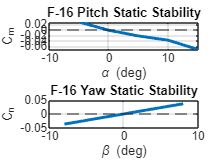


figure;
subplot(2,1,1);
plot(rad2deg(alpha_vec),Cm_vec,'LineWidth',2);
hold on;
yline(0,'--');
grid on;
xlabel('\alpha (deg)');
ylabel('C_m');
title('F-16 Pitch Static Stability');

subplot(2,1,2);
plot(rad2deg(beta_vec),Cn_vec,'LineWidth',2);
hold on;
yline(0,'--');
grid on;
xlabel('\beta (deg)');
ylabel('C_n');
title('F-16 Yaw Static Stability');


%% Dynamic Stability
fprintf('\nDynamic Stability \n');


Dynamic Stability 



evals = eig(A);

fprintf('Eigenvalues:\n');

Eigenvalues:



for k = 1:numel(evals)
fprintf('  %+.4f  %+.4fi\n',real(evals(k)),imag(evals(k)));
end

  +0.0000  +0.0000i
  +0.0000  +0.0000i
  +0.0000  +0.0000i
  -0.5425  +1.3833i
  -0.5425  -1.3833i
  -0.1354  +2.2391i
  -0.1354  -2.2391i
  +0.0001  +0.0537i
  +0.0001  -0.0537i
  -0.0033  +0.0000i
  -0.3877  +0.0000i
  -0.0078  +0.0000i



fprintf('\nDynamic Modes:\n');


Dynamic Modes:



if isfield(modes,'phugoid') && ~isempty(modes.phugoid)
fprintf('  Phugoid      -- zeta = %.4f  T = %.2f s\n',modes.phugoid.damping,modes.phugoid.period);
end

  Phugoid      -- zeta = -0.0019  T = 117.01 s



if isfield(modes,'short_period') && ~isempty(modes.short_period)
fprintf('  Short period -- zeta = %.4f  T = %.2f s\n',modes.short_period.damping,modes.short_period.period);
end

  Short period -- zeta = 0.0604  T = 2.81 s



if isfield(modes,'dutch_roll') && ~isempty(modes.dutch_roll)
fprintf('  Dutch roll   -- zeta = %.4f  T = %.2f s\n',modes.dutch_roll.damping,modes.dutch_roll.period);
end

if isfield(modes,'roll_subsidence') && ~isempty(modes.roll_subsidence)
fprintf('  Roll subsid. -- tau = %.3f s\n',modes.roll_subsidence.time_constant);
end

  Roll subsid. -- tau = 2.579 s



if isfield(modes,'spiral') && ~isempty(modes.spiral)
fprintf('  Spiral       -- tau = %.3f s  stable = %d\n',modes.spiral.time_constant,modes.spiral.stable);
end

  Spiral       -- tau = 128.222 s  stable = 1



%% Reference Summary
ref_point = ac.get_reference_point();
cg_current = ac.mass.get_cg();
ref_point = ref_point(:);
cg_current = cg_current(:);
cg_shift = cg_current - ref_point;
